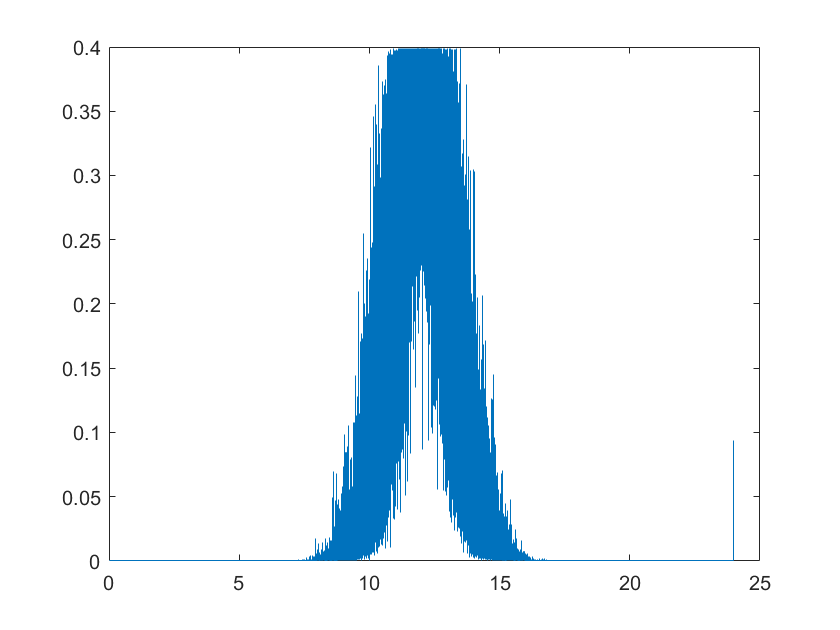

%pd = makedist('Normal','mu',12,'sigma',4) here instead of using makedist
%to create our data I use normrnd as the question says that the temperature
%fluctuations change with time thus normrnd helps give a better estimate
%for our data of the thermometer. The bad data points are then added into
%the distribution. I used the 68-95-99.7 rule of statistics and use a 3sigma
%length od data to be cut out then see how efficiently the bad data points
%are filtered out using a truth table. 
badata = [10., 10.3, 2.1, 0., 0., 15.6, 22.3, 12.7];
data = [(normrnd(12,0.4,[1,100000])),(badata)];
Dip = normpdf(data,linspace(0,24,100008));
stairs(linspace(0,24,100008),Dip)

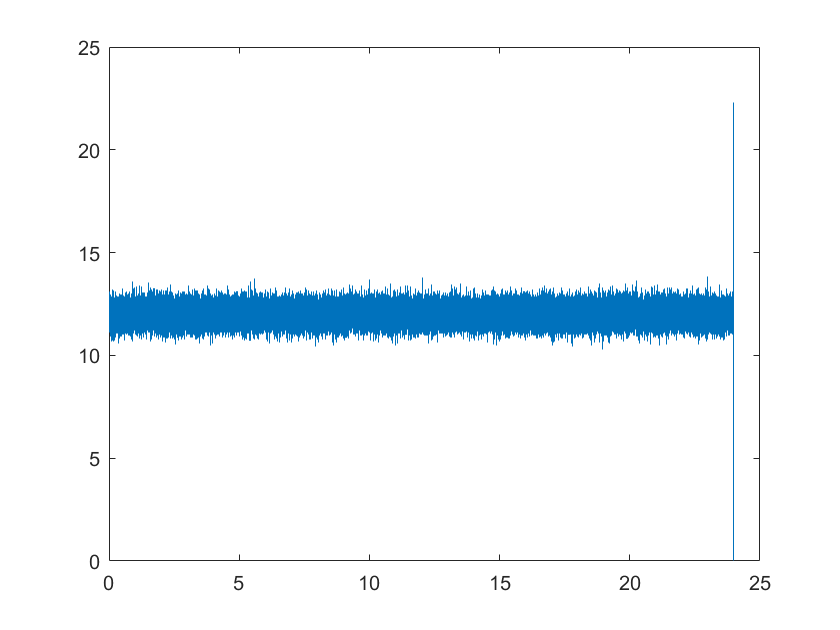

Dn = [(Dip),(badata)];
x1 = size(Dn);
stairs(linspace(0,24,100008),data)

stdev = std(data);
sigma = stdev

sigma = 0.4063

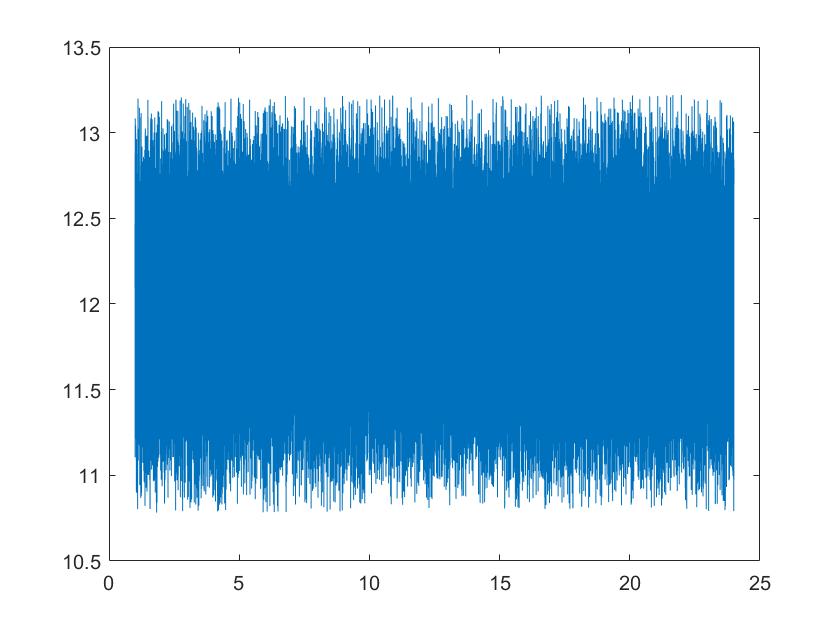

n = 3;
b1 = 12+(n*sigma);
b2 = 12-(n*sigma);
C = data<b1;
nd1 = C.*data ;
C2 = b2<nd1;
nd2 = C2.*nd1;
nd3 = nd2(:,~(nd2==0));
plot(linspace(1,24,max(size(nd3))),nd3)

%truth table 
%Yes there are possibilities of bad data getting in as if one of the bad
%data points is closer to the actual data  it may be diicult to seperate
%them out just by using the 68-95-99.7 rule in statistics. Here the point
%12.7 comes within that range also since our original recorded datat has soo many fluctuation
% that ruling out the possibility that the dataset may already contain numbers near or equal to the 
% bad data points  thus there is one true negative and the other
%7 bad data points are in the false positive. As one increases the size of
%the data they use more and more bad data points now are in the the
%filtered data, thus decreasing the false positive thus making the filtering
%out inefficient.
noF = find(~C2);
valfn = data(noF);
for j = 1:1:7
        t1p = nd3(end-j:end)~=badata(1:j+1);
        if sum(t1p)<= 7
            tp = max(size(nd3(1:end-sum(t1p))));
        end
        f1n = nd3(end-j:end)==badata(1:j+1);
        if sum(f1n)>= 1
            tn = sum(f1n);
        end
        t1n = valfn(end-j+1:end)==badata(1:j);
    if sum(t1n) <= 7
        fp = max(size(t1n));
    end
        f1p = valfn(end-j+1:end)~=badata(1:j); 
        if sum(f1p)==0
            fn = max(size(valfn)-size(f1p));
        end
end
name = {'Pos';'Neg'};
True = [tp;tn];
False = [fp;fn];
T = table(name,True,False)  

T = 2×3 table
    name     True     False
    _____    _____    _____

    'Pos'    99756       7 
    'Neg'        1     238 


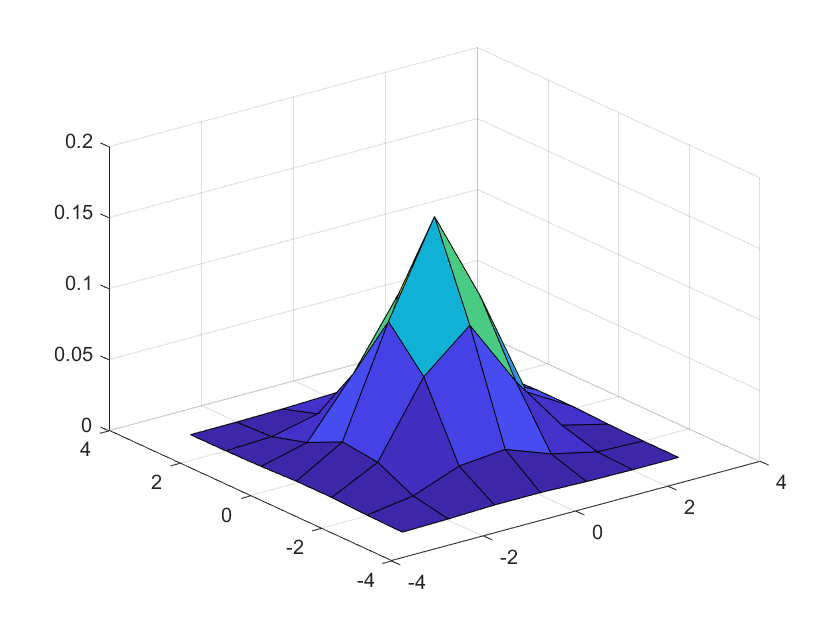

%2
%To mimic the data in the image i use a gaussian distribution with peak
%value at 0.175 within a range of -3,3 with RMS or std =1. 
mu2 = [0 0];
sigma2 = [ 1, 0.175;0.175 ,1];
q1 = -3:1:3;
q2 = -3:1:3;
[X1 ,X2] = meshgrid(q1,q2);
X = [X1(:), X2(:)];
y = mvnpdf(X,mu2,sigma2);
y = reshape(y,length(q2),length(q1));
surf(q1,q2,y)

delx = sum(std2(y)*log(2))*5

delx = 0.1230

zscore = (7-mean2(y))/std2(y)

zscore = 196.6681

tscore = (mean2(y)- mean2(X))*7/(std2(X))

tscore = 0.0710

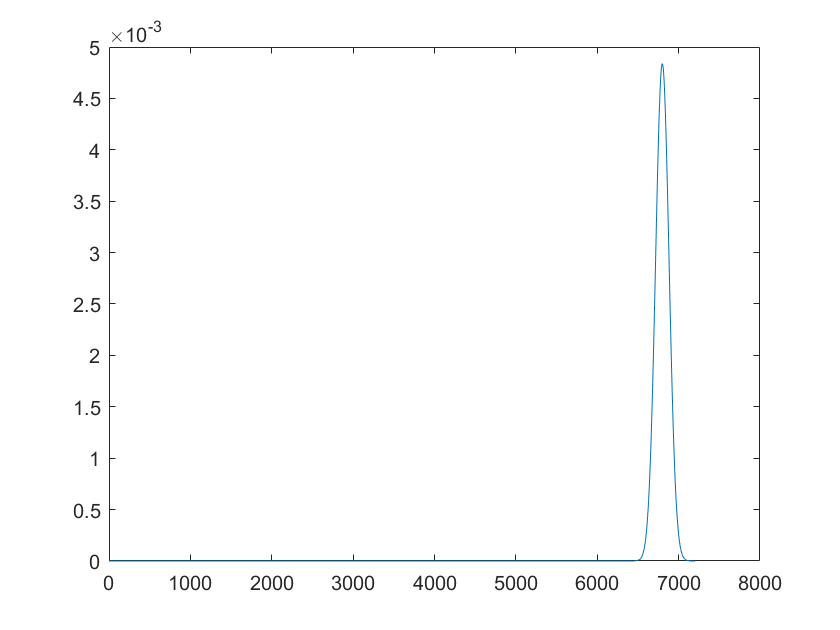



%3
tr = 8*15*60;
to = 6800;
td = [1:tr];
pd3 = makedist('Poisson','lambda',6800);
Pdist = pdf(pd3,td);
plot(linspace(1,7200,7200),Pdist)

lim = sd<2.68*10^-7;
sd = normpdf(td,6800,sqrt(6800));
limits = [9, 7200];
ints3 = normcdf(sd,6800,6800);
intf = find(lim(7140:end));
fivesigma = 7140+intf(1)

fivesigma = 7167

significance = 5*6800/fivesigma

significance = 4.7440